# Project: Find Optimal Buying-low Selling-high Strategy for mean-reverting stock

## Old Town Root

## Simulate the Stock Price with Brownian Motion:

The stock price is $S\left(t\right)\;=e^{X\left(t\right)}$ where $X\left(t\right)$ is governed by the differential equation below:


$$\textrm{dX}\left(t\right)=\lambda \left(\mu -X\left(t\right)\right)\textrm{dt}+\sigma \;\textrm{dW}\left(t\right)$$


$\lambda$ = Speed of mean reversion

$\mu$ = Long run mean

$\sigma$ = Volatility of the process

clf;
clear;

NSample = 100;
N_T = 100;
T = 100;
t0=0;

[TProcess, BProcess] = BrownMotion(NSample, t0, 0, T, N_T);

t0=0;
y0 = [2];
h = (T - t0) / N_T;


stock_prices = [];

for k=1:NSample
    w_diff = diff(BProcess(:, k));
%     w_diff = normrnd(0, sqrt(h), N_T-1);
    x_prime = @(t, y) 0.8 * (2 - y(1)) + 0.5 * (w_diff(int32(t / h) + 1));
    f = {x_prime};
    
    [ymat, t] = EulerSystem(f, t0, y0, T, N_T);
    stock_prices = cat(2, stock_prices, exp(ymat(:, 1)));
end

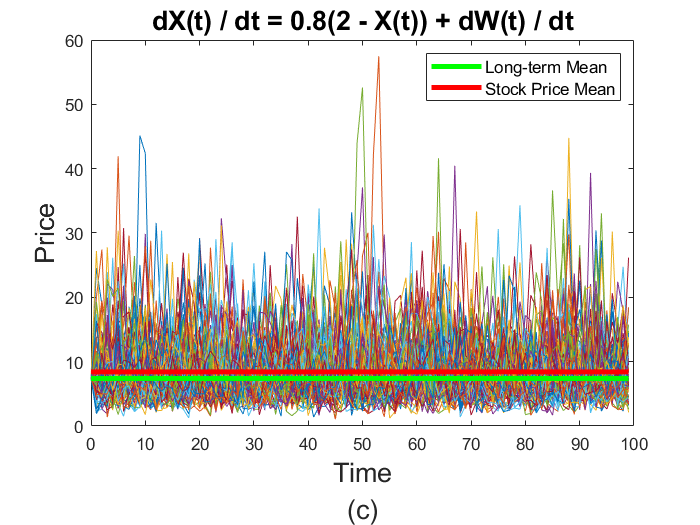

clf;
for k=1:NSample
    plot(t, stock_prices(:, k))
    hold on
end
p(1) = plot(t, ones(length(t), 1) * exp(2),'g','LineWidth',3, 'DisplayName', "Long-term Mean");
p(2) = plot(t, ones(length(t), 1) * mean(mean(stock_prices)),'r','LineWidth',3, 'DisplayName', "Stock Price Mean");
title("dX(t) / dt = 0.8(2 - X(t)) + dW(t) / dt",'FontSize', 16)
xlabel({"Time", "(c)"}, 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
legend(p, 'FontSize', 10)
hold off

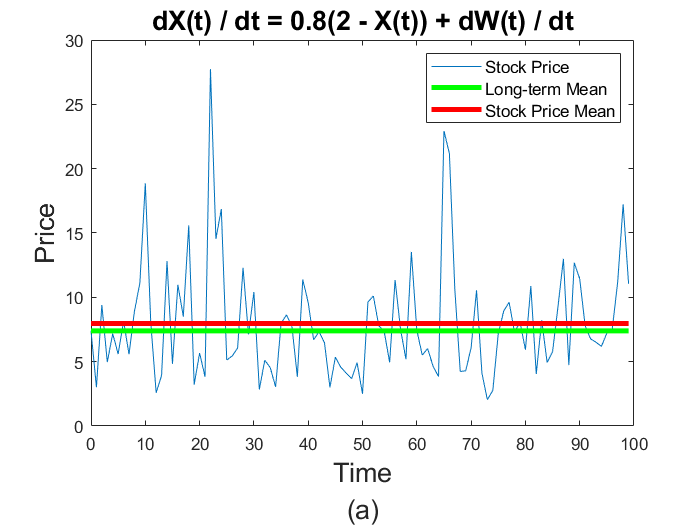

clf;
plot(t, stock_prices(:, 2))
hold on
plot(t, ones(length(t), 1) * exp(2),'g','LineWidth',3)
plot(t, ones(length(t), 1) * mean(stock_prices(:, 2)),'r','LineWidth',3)
hold off
title("dX(t) / dt = 0.8(2 - X(t)) + dW(t) / dt",'FontSize', 16)
xlabel({"Time", "(a)"}, 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
legend("Stock Price", "Long-term Mean", "Stock Price Mean",'FontSize', 10)

## Following what Prof. Dharmavaram has said 

## (Global Optimization):

Calculate the reward over multiple possible trends of stock prices given the same initial conditions.

b0 = 5

b0 = 5

s0 = 18

s0 = 18

reward =    11.2722   12.5929   13.5267   14.2892   13.8721   14.4627   15.0019   14.6706   15.1375   15.5777   15.2942   15.6924   15.4314   15.7977   16.1507   15.9114   16.2416   16.0161   16.3274   16.6303   16.4215   16.7097   16.5102   16.7856   17.0551   16.8674   17.1264   16.9455   17.1951   17.4403   17.2683   17.5055   17.3388   17.5686   17.4067   17.6300   17.8501   17.6946   17.9088   17.7573   17.9661   18.1723   18.0261   18.2275   18.0846   18.2814   18.1416   18.3342   18.5248   18.3891


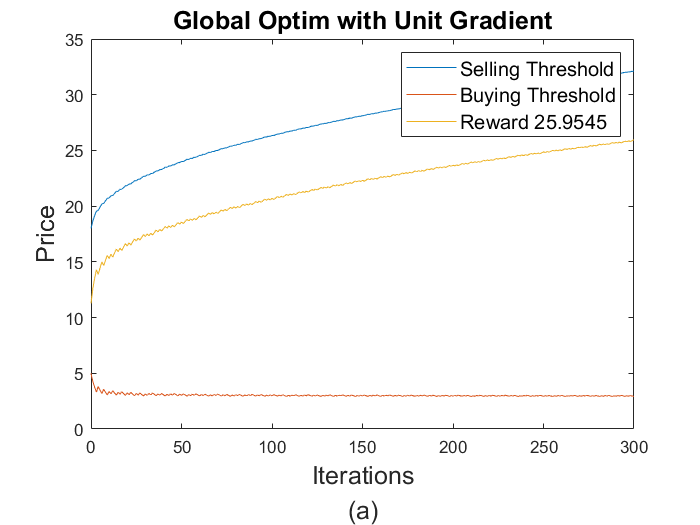

reward =    11.2722   13.1384   14.4580   14.4149   15.3480   16.1826   16.1521   16.8575   16.8311   17.4532   17.4296   17.9923   17.9707   18.4883   18.4684   18.9502   18.9316   19.3842   19.3666   19.7947   19.7780   20.1853   20.1694   20.5585   20.5433   20.9165   20.9019   21.2610   21.2469   21.5935   21.5798   21.9150   21.9018   22.2267   22.2139   22.5293   22.5169   22.8237   22.8116   23.1104   23.0986   23.3901   23.6780   23.6667   23.9480   23.9369   24.2120   24.2012   24.4705   24.4599


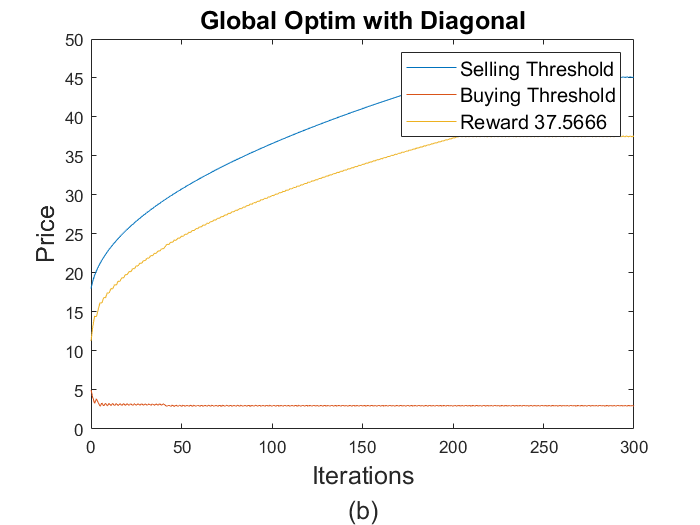

reward =    11.2722   12.2426   12.9288   12.3685   12.8537   13.2877   12.8915   13.2583   12.9152   13.2387   12.9318   13.2244   12.9443   13.2134   12.9541   13.2046   12.9620   13.1974   12.9687   13.1913   12.9743   13.1861   12.9792   13.1815   12.9834   13.1775   12.9872   13.1739   12.9906   13.1708   12.9936   13.1679   12.9963   13.1653   12.9988   13.1629   13.0011   13.1607   13.0032   13.1586   13.0052   13.1567   13.3065   13.1585   13.3048   13.1601   13.3032   13.1617   13.3017   13.1631


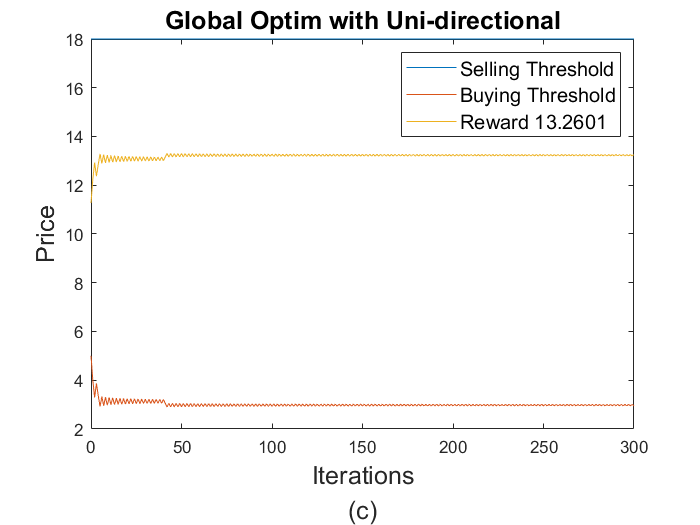

num_iter = 300;

rewards = {};
s_s = {};
b_s = {};
strategis = ["Adaptive Gradient", "Unit Gradient", "Diagonal", "Uni-directional"];
x_labels = ["0", "(a)", "(b)", "(c)"];

for mode=1:3
    s = [];
    b = [];
    reward = [];
    b(1) = b0;
    s(1) = s0;
    for iter=1:num_iter    
        c = (iter) ^ (-1/2);
        reward(iter) = TransactionReward(stock_prices, b(iter), s(iter), T);
        
        incre_b = b(iter) + c;
        reward_incre_b = TransactionReward(stock_prices, incre_b, s(iter), T);
        
        decre_b = b(iter) - c;
        reward_decre_b = TransactionReward(stock_prices, decre_b, s(iter), T);
        
        incre_s = s(iter) + c;
        reward_incre_s = TransactionReward(stock_prices, b(iter), incre_s, T);
        
        decre_s = s(iter) - c;
        reward_decre_s = TransactionReward(stock_prices, b(iter), decre_s, T);
        
        gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
        gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
        
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        [next_b, next_s] = update_bs(b(iter), s(iter), ...
            gradient_b, gradient_s, ...
            iter, c, mode);
        
        b(iter + 1) = next_b;
        s(iter + 1) = next_s;
        
        change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
        if iter > 1 && change < 0.001
            break
        end
    end
    reward(iter + 1) = TransactionReward(stock_prices, b(iter + 1), s(iter + 1), T)
    
    figure()
    plot(linspace(0, length(reward) - 1, length(reward)), s)
    hold on
    plot(linspace(0, length(reward) - 1, length(reward)), b)
    plot(linspace(0, length(reward) - 1, length(reward)), reward)
    legend("Selling Threshold", "Buying Threshold", "Reward" + " " + string(reward(end)), "FontSize", 12)
    title("Global Optim with " + strategis(mode + 1), "FontSize", 15)
    hold off
    rewards{mode + 1} = reward;
    s_s{mode + 1} = s;
    b_s{mode + 1} = b;
    ylabel("Price", "FontSize", 15)
    xlabel({"Iterations", x_labels(mode + 1)}, "FontSize", 15)
end

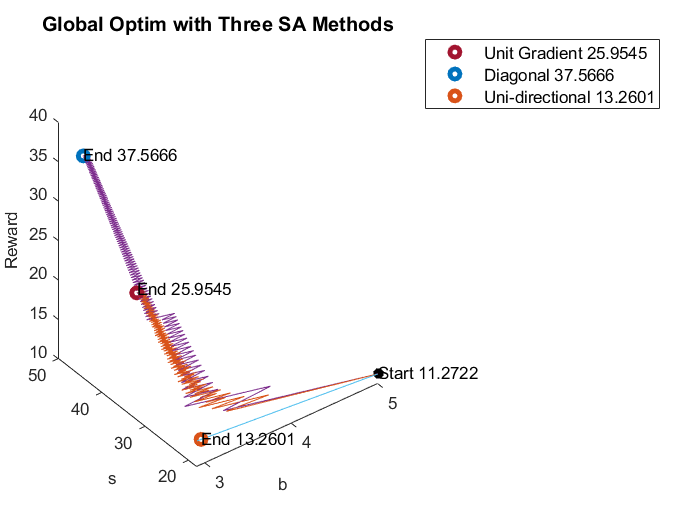

clf;
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    plot3(b(1), s(1), reward(1), "*black", "linewidth", 3)
    hold on
    plot3(b, s, reward)
    hold on
    if i == 2
       text(b(end), s(end), reward(end) + 0.6, append('End ', string(reward(end)))) 
    else
       text(b(end), s(end), reward(end) + 0.2, append('End ', string(reward(end)))) 
    end
end
text(b_s{i}(1), s_s{i}(1), rewards{i}(1) + 0.2, append('Start ', string(rewards{i}(1))))

p = [];
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    p(i-1) = plot3(b(end), s(end), reward(end), "o", "linewidth", 3, 'DisplayName', strategis(i) + " " + string(reward(end)));
end

xlabel("b", "FontSize", 10)
ylabel("s", "FontSize", 10)
zlabel("Reward", "FontSize", 10)
title("Global Optim with Three SA Methods", "FontSize", 12)

legend(p, "FontSize", 10)

## Before Optimizing:

What we gain by using the initial buying and selling threshold to perform one transaction on one of the stocks.

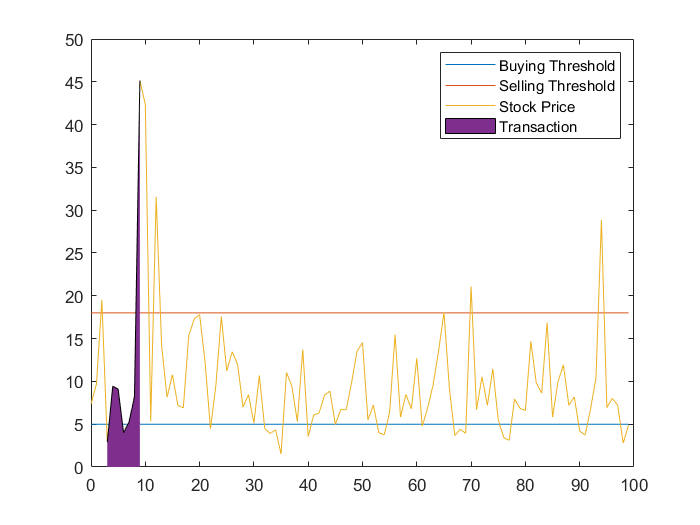

[tau_b,ColNrs] = find(stock_prices(:, 1) < b0);
[tau_s,ColNrs] = find(stock_prices(:, 1) > s0);
[tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));

clf;
plot(t, ones(length(t), 1) * b0)
hold on
plot(t, ones(length(t), 1) * s0)
plot(t, stock_prices(:, 1))

one_buy_time = tau_b(1);
one_sell_time = tau_s(1);
ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
yz = stock_prices(one_buy_time:one_sell_time, 1);
area(ix, yz)

legend("Buying Threshold", "Selling Threshold", "Stock Price", "Transaction")

disp("Total revenue before Optimization")

Total revenue before Optimization


phi = exp(-0.01 * tau_s(1) / length(stock_prices(:, 1)) * T) * s0 * (1 - 0.01) - exp(-0.01 * tau_b(1) / length(stock_prices(:, 1)) * T) * b0 * (1 + 0.01)

phi = 11.2722

## After Optimization:

What we gain using the optimized buying and selling threshold to perform one transaction on the same stock

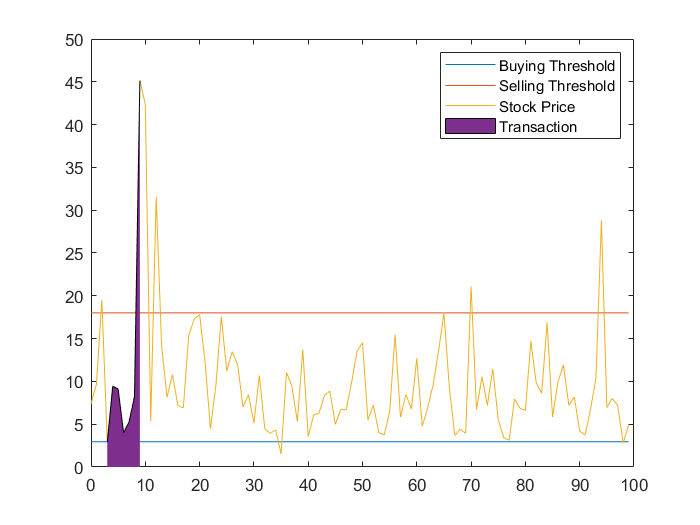

[tau_b,ColNrs] = find(stock_prices(:, 1) < b(end));
[tau_s,ColNrs] = find(stock_prices(:, 1) > s(end));
[tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));

clf;
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, stock_prices(:, 1))

one_buy_time = tau_b(1);
one_sell_time = tau_s(1);
ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
yz = stock_prices(one_buy_time:one_sell_time, 1);
area(ix, yz)

legend("Buying Threshold", "Selling Threshold", "Stock Price", "Transaction")

disp("Total revenue after Optimization");

Total revenue after Optimization


phi = exp(-0.01 * tau_s(1) / length(stock_prices(:, 1)) * T) * s(end) * (1 - 0.01) - exp(-0.01 * tau_b(1) / length(stock_prices(:, 1)) * T) * b(end) * (1 + 0.01)

phi = 13.2601

## Following what I have thought (Local Optimization):

Use only one OU functions, but buy and sell multiple times in one period.

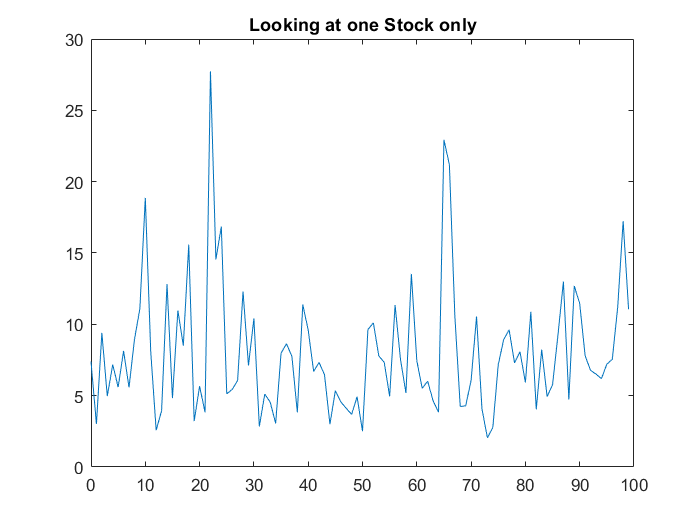

b0 = 5;
s0 = 18;
num_iter = 300;

% stock_price = stock_prices(:, randi(NSample));
stock_price = stock_prices(:, 2);

clf;
plot(t, stock_price)
title("Looking at one Stock only")
hold off

reward =    26.3979   29.5021   31.7462   32.7442   30.9792   32.7410   31.2582   32.7467   31.4535   31.4195   32.6650   31.9030   33.0397   32.7847   32.0912   33.1095   32.1837   33.1401   32.8478   32.2365   33.1184   32.8205   32.2465   33.0688   33.8738   33.1289   32.8313   33.5903   33.0725   33.8048   33.1239   32.8318   33.5290   33.0479   33.7242   33.0933   32.8086   33.4569   33.0057   33.6372   33.3559   32.9202   33.5287   33.2528   32.8309   33.4188   34.0003   33.4546   33.1868   33.7502


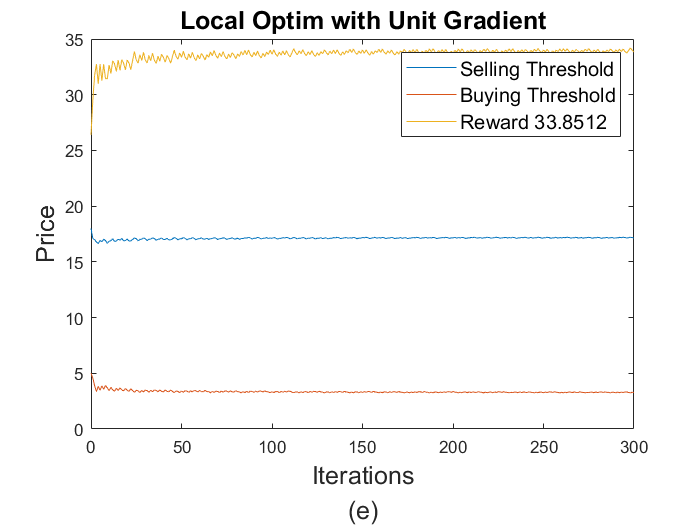

reward =    26.3979   31.1736   31.6983   31.4369   31.6633   31.4608   33.7302   31.6291   33.5945   31.7415   33.4994   31.8233   33.4280   31.8863   33.3719   31.9367   33.3264   33.4362   33.3295   33.4333   33.3321   33.4309   33.3344   33.4288   33.3363   33.4269   33.3381   33.4252   33.3397   33.4237   33.3411   33.4224   33.3424   33.4212   33.3435   33.4201   33.3446   33.4190   33.3456   33.4181   33.3465   33.4172   33.3473   33.4164   33.3481   33.4156   33.3489   33.4149   33.3496   33.4142


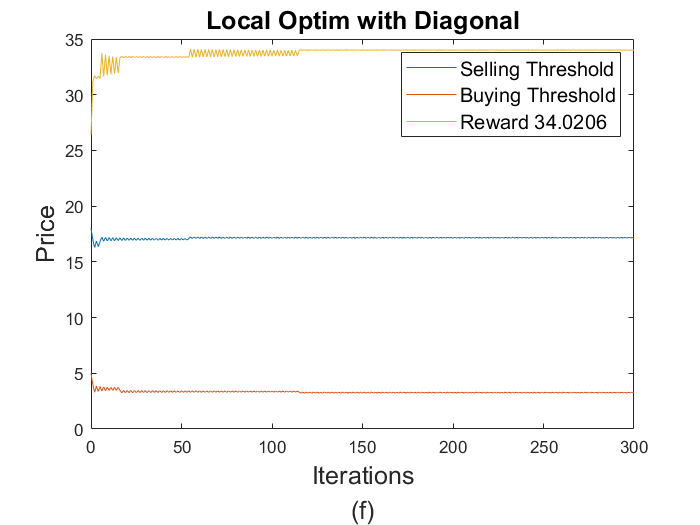

reward =    26.3979   27.9587   30.1733   32.2332   30.4945   32.0745   33.3016   32.1655   31.2629   32.2648   31.3143   32.2206   31.3529   32.1865   31.3832   32.1593   31.4079   32.1369   31.4284   32.1180   32.7901   32.1342   32.7750   32.1483   32.7618   32.1607   32.7501   32.1717   32.7397   32.1815   32.7303   32.1905   32.7218   32.1986   32.7141   32.2060   32.7070   32.2128   32.7004   32.2191   32.6944   32.2249   32.6887   32.2304   32.6835   32.2354   32.6786   32.2402   32.6740   32.2446


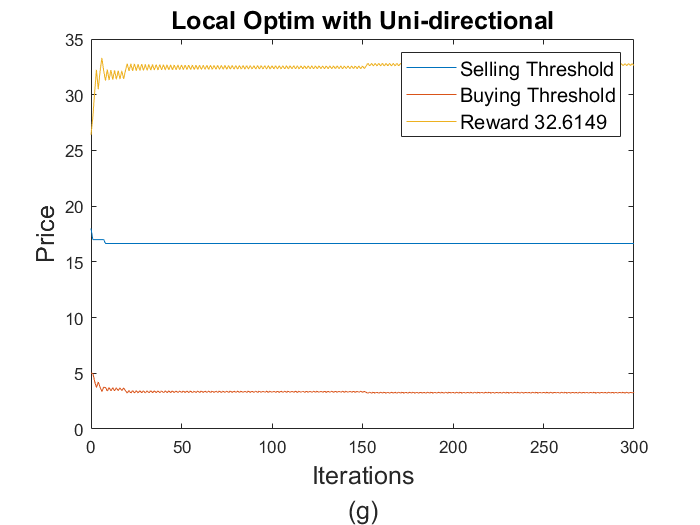


rewards = {};
s_s = {};
b_s = {};
strategis = ["Adaptive Gradient", "Unit Gradient", "Diagonal", "Uni-directional"];
x_labels = ["0", "(e)", "(f)", "(g)"];

for mode=1:3
    s = [];
    b = [];
    reward = [];
    b(1) = b0;
    s(1) = s0;
    for iter=1:num_iter
        c = (iter) ^ (-1/2);
        reward(iter) = MultiTransactionReward(stock_price, b(iter), s(iter), T);
        
        incre_b = b(iter) + c;
        reward_incre_b = MultiTransactionReward(stock_price, incre_b, s(iter), T);
        
        decre_b = b(iter) - c;
        reward_decre_b = MultiTransactionReward(stock_price, decre_b, s(iter), T);
        
        incre_s = s(iter) + c;
        reward_incre_s = MultiTransactionReward(stock_price, b(iter), incre_s, T);
        
        decre_s = s(iter) - c;
        reward_decre_s = MultiTransactionReward(stock_price, b(iter), decre_s, T);
        
        gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
        gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
        
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        [next_b, next_s] = update_bs(b(iter), s(iter), ...
            gradient_b, gradient_s, ...
            iter, c, mode);
        
        b(iter + 1) = next_b;
        s(iter + 1) = next_s;
        
        change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
        if iter > 1 && change < 0.001
            break
        end
    end
    
    reward(iter + 1) = MultiTransactionReward(stock_price, b(iter + 1), s(iter + 1), T)
    
    figure()
    plot(linspace(0, length(reward) - 1, length(reward)), s)
    hold on
    plot(linspace(0, length(reward) - 1, length(reward)), b)
    plot(linspace(0, length(reward) - 1, length(reward)), reward)
    legend("Selling Threshold", "Buying Threshold", "Reward" + " " + string(reward(end)), "FontSize", 12)
    title("Local Optim with " + strategis(mode + 1), "FontSize", 15)
    hold off
    rewards{mode + 1} = reward;
    s_s{mode + 1} = s;
    b_s{mode + 1} = b;
    ylabel("Price", "FontSize", 15)
    xlabel({"Iterations", x_labels(mode + 1)}, "FontSize", 15) 
end

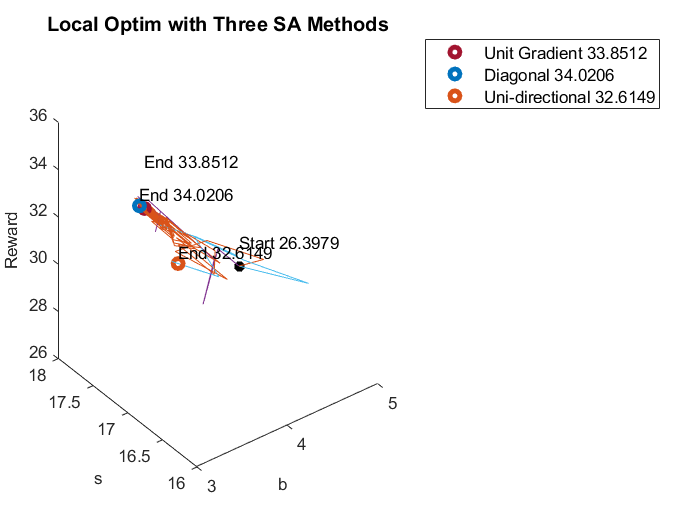

clf;
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    plot3(b(1), s(1), reward(1), "*black", "linewidth", 3)
    hold on
    plot3(b, s, reward)
    hold on
    if i == 2
       text(b(end), s(end), reward(end) + 2, append('End ', string(reward(end)))) 
    else
       text(b(end), s(end), reward(end) + 0.5, append('End ', string(reward(end)))) 
    end
end
text(b_s{i}(1), s_s{i}(1), rewards{i}(1) + 1, append('Start ', string(rewards{i}(1))))

p = [];
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    p(i-1) = plot3(b(end), s(end), reward(end), "o", "linewidth", 3, 'DisplayName', strategis(i) + " " + string(reward(end)));
end

xlabel("b", "FontSize", 10)
ylabel("s", "FontSize", 10)
zlabel("Reward", "FontSize", 10)
title("Local Optim with Three SA Methods", "FontSize", 12)

legend(p, "FontSize", 10)

b(end), s(end), reward(end)

ans = 3.2882

ans = 16.6464

ans = 32.6149

## Using the inital Buying and Selling Thresholds:

Much less gross income from all transactions.

one_stock_price = stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b0 and s0

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b0, s0); 

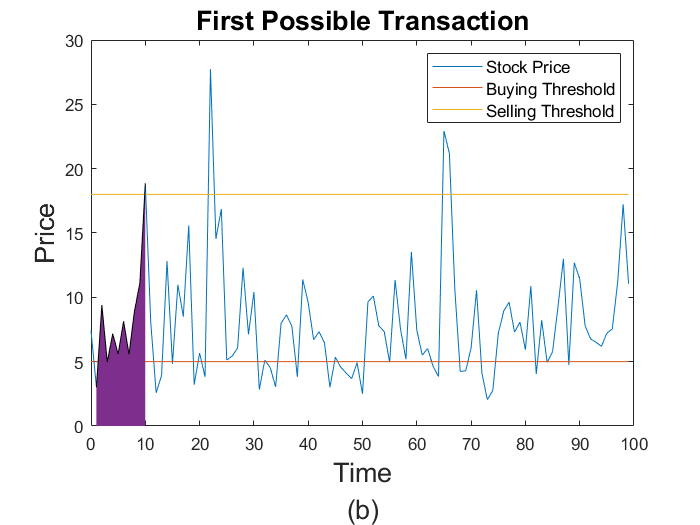

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, one_stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)


for i=1:1
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Stock Price", "Buying Threshold", "Selling Threshold", "FontSize", 10)
title("First Possible Transaction", "FontSize", 16)
xlabel({"Time", "(b)"}, 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

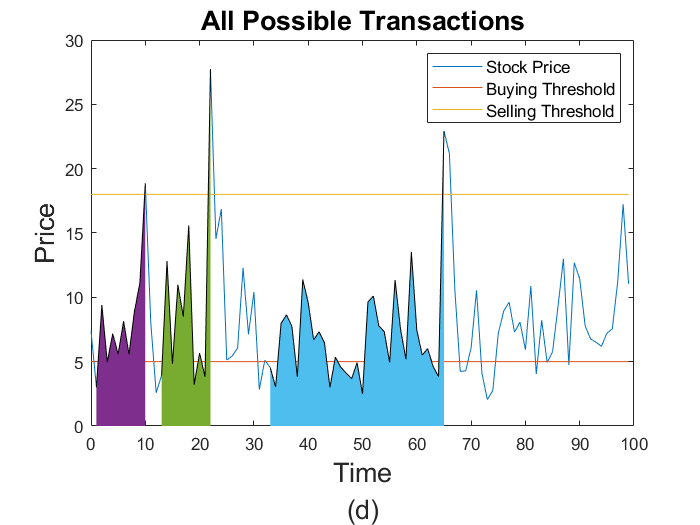

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, one_stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)


for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Stock Price", "Buying Threshold", "Selling Threshold", "FontSize", 10)
title("All Possible Transactions", "FontSize", 16)
xlabel({"Time", "(d)"}, 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

## Compute Revenue using the initial Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s0 * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b0 * (1 + 0.01)

phi =    11.0138    9.7683    5.6159


disp("Total revenue before Optimization")

Total revenue before Optimization


phi = sum(phi)

phi = 26.3979

## Using the optimized Buying and Selling Thresholds:

We get a better sum of revenues from all transactions we made.

one_stock_price = stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b and s

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b(end), s(end)); 

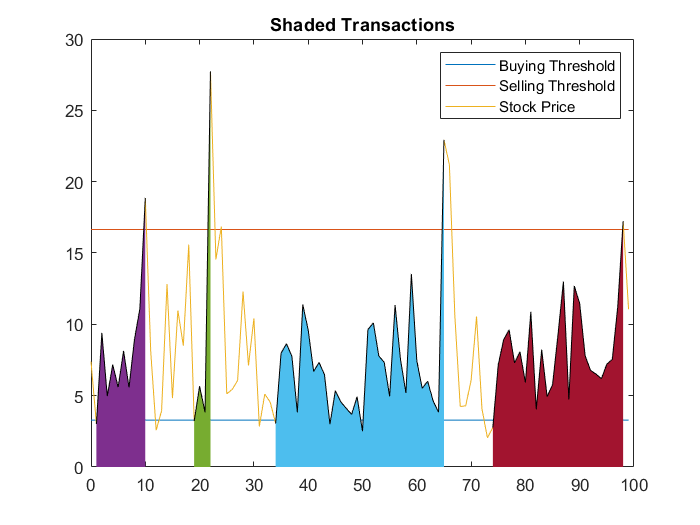

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Buying Threshold", "Selling Threshold", "Stock Price")
title("Shaded Transactions")
hold off

## Compute Revenue using the Optimized Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s(end) * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b(end) * (1 + 0.01)

phi =    11.5080   10.3748    6.1774    4.5548


disp("Total revenue after Optimization")

Total revenue after Optimization


phi = sum(phi)

phi = 32.6149

## Explore the reward function on all possible '`b'` and 's':

% Explore the surface of the reward function at all possible b and s
% b and s are the x and y axes of the plot
% and the surface (z) is the reward computed at a given (b, s)
s_all = linspace(3, 23, 50);
b_all = linspace(3, 23, 50);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = MultiTransactionReward(stock_price, b_all(i), s_all(j), T);
    end
end

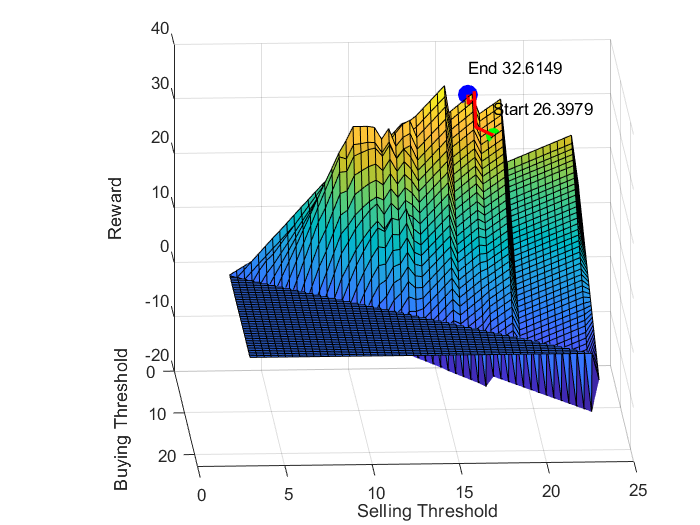

clf;
surf(b_all, s_all, reward_all)
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
%zlim([-50, 50])
hold on

plot3(b(1), s(1), reward(1), 'ogreen','linewidth',3)
plot3(b, s, reward, 'red','linewidth',2)
plot3(b(end), s(end), reward(end), 'oblue','linewidth',6)
text(b(1), s(1), reward(1) + 5, append('Start ', string(reward(1))))
text(b(end), s(end), reward(end) + 5, append('End ', string(reward(end))))
hold off

## Interactive Plot:

that shows how our algorithm are finding the local maximum of that reward function

s_all = linspace(3, 23, 500);
b_all = linspace(3, 23, 500);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = MultiTransactionReward(stock_price, b_all(i), s_all(j), T);
    end
end

Interactive plot. Go to the next optimal point by pressing the key "k" on the keyboard.

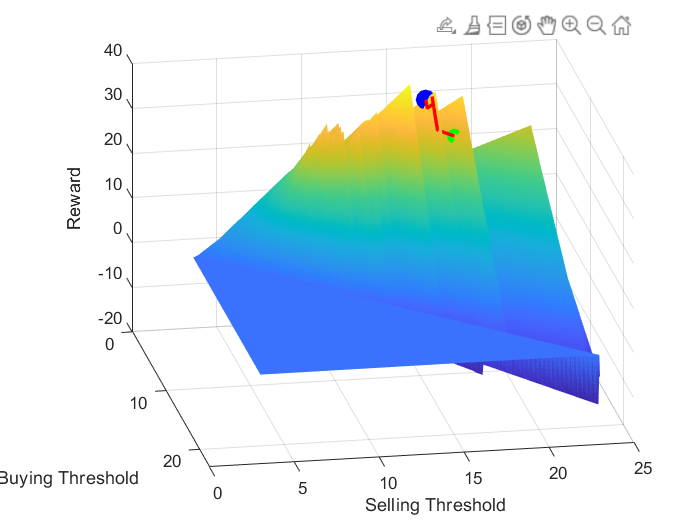

clf;
h = surf(b_all, s_all, reward_all);
set(h,'LineStyle','none')
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
hold on

plot3(b(1), s(1), reward(1), 'ogreen','linewidth',3)
step = 5;
for i=1:step:length(s)-1
    key_press = waitforbuttonpress;
    val = get(gcf, "CurrentCharacter");
    while val ~= "k"
        key_press = waitforbuttonpress;
        val = get(gcf, "CurrentCharacter");
    end
    if i ~= 1
        delete(h);
    end
    plot3(b(i:i+ step -1), s(i:i+ step -1), reward(i:i+ step -1), 'red','linewidth',2)
    h = plot3(b(i+step -1), s(i+ step -1), reward(i+ step -1), 'oblue','linewidth',3);
    hold on
end
delete(h)
plot3(b(end), s(end), reward(end), 'oblue','linewidth',6)
hold off

key_press = waitforbuttonpress

key_press = 1

val = get(gcf, "CurrentCharacter")

val = 'k'

# Function Definitions:

function [ymat, t]=EulerSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / N;
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N
        for i=1:length(y0)
            ymat(j, i) = ymat(j - 1,i) + h * f{i}(t(j-1), ymat(j - 1, :));
            t(j) = t(j - 1) + h;
        end
    end
end

function [ymat, t]=RKSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / N;
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N + 1
        for i=1:length(y0)
            k1 = h * f{i}(t(j-1), ymat(j - 1, :));
            k2 = h * f{i}(t(j-1) + h, ymat(j - 1, :) + k1);
            ymat(j, i) = ymat(j - 1,i) + (1 / 2) * (k1 + k2);
            t(j) = t(j - 1) + h;
        end
    end
end

function [TProcess, BProcess]=BrownMotion(sample, t0, y0, b, N)
    BProcess = [];
    TProcess = [];
    NSample = sample;
    N_T = N;
    T = b;
    
    for k = 1:NSample
        B = y0;
        t = t0;
        BProcess(1,k)=B; TProcess(1,k)=t;
        for i=2:N_T
            dt =  T/N_T;
            t = t + dt;
            B = B + sqrt(dt)*randn(1); %increments in B are normally distibuted with variance dt
            BProcess(i,k) = B;
            TProcess(i,k) = t;
        end
    end
end


function [next_b, next_s] = update_bs(b, s, gradient_b, gradient_s, ...
    iter, c, mode)
    eps =0.000001;
    % Update strategy 0 gradient vector
    if mode == 0
        next_b = b + gradient_b / iter;
        next_s = s + gradient_s / iter;
    % Update strategy 1 unit vector
    elseif mode == 1
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        next_b = b + gradient_b / (mag + eps) * c;
        next_s = s + gradient_s / (mag + eps) * c;
    % Update strategy 2 move in diagonal 
    elseif mode == 2
        if gradient_b > 0
            next_b = b + c;
        else
            next_b = b - c;
        end
        
        if gradient_s > 0
            next_s = s + c;
        else
            next_s = s - c;
        end
    % Update strategy 3 move in largest gradient (eithr b or s)
    elseif mode == 3
        if abs(gradient_s) > abs(gradient_b)
            next_b = b;
            if gradient_s > 0
                next_s = s + c;
            else
                next_s = s - c;
            end
        else
            next_s = s;
            if gradient_b > 0
                next_b = b + c;
            else
                next_b = b - c;
            end
        end
    end
end


% Global Optimization
% Optimize on one transaction of multiple different stock prices
function reward=TransactionReward(stock_prices, b, s, T)
    if b > s
        reward = 0;
        return
    end
    phi = [];
    for k=1:length(stock_prices(1))
        [tau_b,ColNrs] = find(stock_prices(:, k) < b);
        [tau_s,ColNrs] = find(stock_prices(:, k) > s);
        if length(tau_b) < 1
            continue
        end
        [tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));
        if length(tau_s) < 1
            continue
        end
        tau_b = tau_b(1);
        phi(k) = exp(-0.01 * tau_s / length(stock_prices) * T) * s * (1 - 0.01) - exp(-0.01 * tau_b / length(stock_prices) * T) * b * (1 + 0.01);
    end
    
    if length(phi) < 1
        reward = 0;
    else
        reward = mean(phi);
    end       
end


% Local Optimization
% Optimize on multiple transaction of one randomly chosen stock
function reward=MultiTransactionReward(one_stock_price, b, s, T)
    if b > s
        reward = 0;
        return
    end
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        RowNrs = [];
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    break
                end
                if prev_s > length(tau_s)
                    break
                end
                i = RowNrs(1);
                break
            end
        end
        if length(RowNrs) < 1 
            break
        end
        if prev_s > length(tau_s)
            break
        end
        i = i + 1;
    end
    
    tau_b = buy_times;
    tau_s = sell_times;
    
    if length(tau_b) < 1
        reward = 0;
    else
        phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b * (1 + 0.01);
        reward = sum(phi);
    end
end


function [buy_times, sell_times]=find_set_of_selling_buying_time(one_stock_price, b, s)
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    return
                end
                if prev_s > length(tau_s)
                    return
                end
                i = RowNrs(1);
                break
            end
        end
        i = i + 1;
    end
end